# Numerical Computation on "Impulse Response of a Hypothetical Blackhole on a Body in Space-Time Linearly"

### Abstract

What's the force's magnitude of an object when it approaches a hypothetical blackhole of mass 100 times that of Sun over a very short time period? Well, this proposal mainly talks about the numerical computation of impulse response of the blackhole on it. The computation part of this paper is done Euler method in MATLAB. The problem is solved by inserting domain values at very point of the given functions. The purpose of this proposal is to calculate the impulse response.

### **Introduction**

This paper has occuired motivation to be done because we know what's an Impulse function in Classical physics. An Impulse response is nothing but the force experienced by the body in very short time period. When we hit a wall by a wall, the product of the force and time taken to complete the impact is created. We have used Euler method to solve the looping part in the program. 

### **1. Domains**

NP = 100000;
tMax = 1;                              
dt_Our= tMax/NP;     

- Firstly, define the no. of samplings

- More the samplings' count, higher the plotting accuracy

### **2. Constants**

c = 2.999*10^8;                         
v0 = 10^6;                              
G = 6.6743*10^-11;     

- Let '$c$' be velocity of electromagnetic waves

- The velocity of the travelling body is $1\textrm{Million}$ *$\left\lbrack \frac{1m}{1s}\right\rbrack$


m_S = 1.9889*10^30;                     
m_B = 100*m_S;                          
m_b = 1000;         

- $M_S$ is the mass of Sun in $\textrm{Kg}$

- $M_B$ is the mass of the hypothetical blackhole in $\textrm{Kg}$

- $M_b$ is the mass of the body in $\textrm{Kg}$

x_B = ((10^-15)/9.461)*10^19;                             
y_B = 0;                               
z_B = 0;                                

y_b = 0;                               
z_b = 0;

Where,

- $x_B$ is the x-axial distance of the blackhole 

- $x_b$ is the x-axial distance of the body

- $z_b$ is the z-axial distance of the body

- $y_B$ is the y-axial distance of the blackhole

- $y_b$ is the y-axial distance of the body

- $z_B$ is the z-axial distance of the blackhole

### **3. Assigning Arrays**

t = zeros(1, NP);                    
Fg = zeros(1, NP);                      
x_b = zeros(1, NP);                    
r_Bb = zeros(1, NP);                    
dt_b = zeros(1, NP);                   
v = zeros(1, NP);                       

- All the arrays are defined from 0 to NP

### **4. Initial Conditions**                        

x_b(1) = 0;    
v(1) = 0;                               
t(1) = 0;                               

- **On defining initial conditions, we can run looping easily because "for-end" loop can't assign values by it's own**

### **5. Looping**

for i = 1: NP 

- The "for-end" loo[ does calculate values of the given functions at every single domain and sum up them. "i" is the generalized variable domain for looping. The range of it is from 0 to NP with an interval of 1.

    v(i + 1) = v(i) + 0.5*v0;                                                     

- To calculate updated velocity of the moving body is done by Euler method

    dt_b(i) = dt_Our*sqrt(1 - (v(i + 1)/c)^2)^0.5;       

- ${\textrm{dt}}_B$ = ${\textrm{dt}}_{\textrm{Our}}$$\ast \sqrt{\left(1-{\left(\frac{v_r }{c}\right)}^2 \right)}$, an expression that had been formulated to see relativistic linkage between the blackhole and body

    x_b(i + 1) = x_b(i) + v(i + 1)*dt_b(i);                                        

- $X_{b\backslash } \;=v_b \ast {\textrm{dt}}_B$, updating $x_b$ by $v_b$ and ${\textrm{dt}}_B$

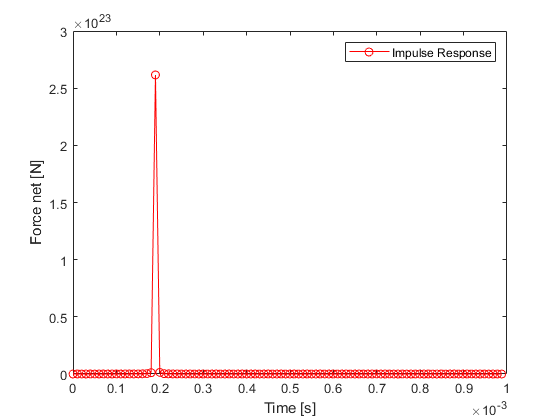

    r_Bb(i + 1) = sqrt((x_B - x_b(i + 1))^2 + (y_B - y_b)^2 + (z_B - z_b)^2); 

- $r_{\textrm{BT}}$ = $\sqrt{\left({\left(\;X_B \;-X_T \right)}^2 \;+\;{\left(Y_B \;-Y_T \right)}^2 \;+{\left(Z_B \;-Z_T \right)}^2 \right)}$, an expression that is ready to calculate the distance between the blackhole and body

    Fg(i) = (G*m_B*m_b/(r_Bb(i + 1))^2) + (m_b*(v(i + 1) - v(i))/dt_b(i));                                        

- $\;F_G$ = $\frac{G\ast M_B \ast M_b }{{r_{\textrm{Bb}} }^2 }$, an expression that has formed by Law of Newton's Gravitation

- $F_{M\;} =M_b \ast \frac{dv_b }{{\textrm{dt}}_B }$, an expression of momentum force formed by differentiation 

- $F_{\textrm{net}} =F_G +F_M$, addition body's forces experience 

    t(i + 1) = t(i) + dt_b(i);         

- $t_{\textrm{new}} =t_{\textrm{old}}$ + $dt_b$, old time gets updates by  $dt_b$

end

- Use "end" to complete looping

### **6. Plotting**

plot(t(1: 100), Fg(1: 100), 'ro-');   
xlabel('Time [s]');                    
ylabel('Force net [N]');                
h = legend('Impulse Response');       

### **8. Conclusion**

- **The Impulse response of a hypothetical blackhole on a body in Space-Time is the area under the curve that is **$d\left(\textrm{Impulse}\right)=F_{\textrm{net}}$$\ast {\textrm{dt}}_B$**.**

- **The magnitude of the force on a very short time duration of **$\approx 2\mu s$ **is almost **$\approx 2\ldotp 62*{10}^{23}$ $N\ldotp$

### **9. Reference**

- [www.nasa.gov.com](www.nasa.gov.com)

- *MATLAB R2020a*

- *www,mathworks.com*